21-09-20

МИУ для Hpol sqr

close all;
clear variables;

% f01 = fopen('I_MIE_sqr_last_pres.dat','w');
% f02 = fopen('DA_MIE_sqr_last_pres.dat','w');


% ВХОДНЫЕ ДАННЫЕ (настройка)

global N as dx

k = 2*pi; % волновое число, при лямде = 1
as = 1/pi; % ширина ленты
N = 100; % количество точек коллокации
phi_grad = 0; % угол падения волны [град]
dx = as/N; % растояние между центрами цилиндров

% замена переменных

Новые константы

kdx = k*dx;
gamma = 1.781072417990;
kd4 = kdx/4;
% dx2 = dx/2;
delta = dx/2;
kd6 = kdx/6;
    D0 = kdx*(1+(1i*2/pi)*(log(gamma*kd4)-1));
    D1 = kdx*(1+(1i/pi)*(3*log(3*gamma*kd4)-log(gamma*kd4)-2));
    D2 = kdx*(1+(1i*2/pi)*(log(2*gamma*kd4)-1));

treshold = 2*dx;

if treshold == dx
    warning('Порог равен dx, один матричный элемен будет вычислен аналитически')    
elseif treshold <= dx
    warning('Порог меньше dx, ни одного матричного элемента не будет вычислено аналитически')    
end

Вычисление координат ВИ

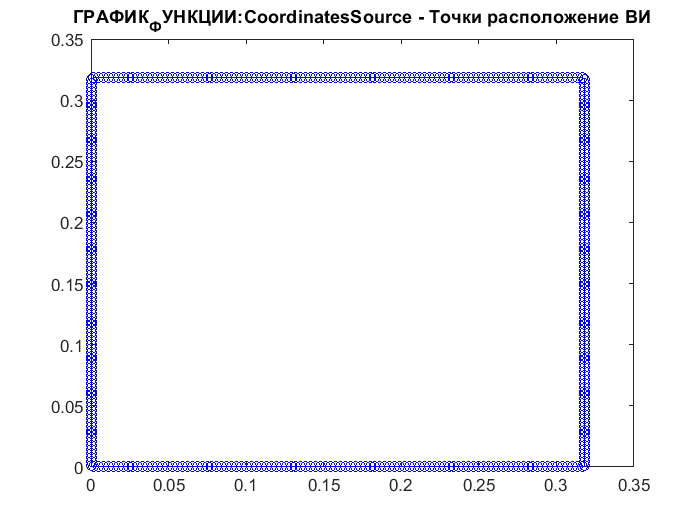

S = 1×4 struct array with fields:
    x
    z


S = CoordinatesSource()

#### Выделим память под все

Es11 = zeros(N, N);
Es12 = zeros(N, N);
Es13 = zeros(N, N);
Es14 = zeros(N, N);
Es21 = zeros(N, N);
Es22 = zeros(N, N);
Es23 = zeros(N, N);
Es24 = zeros(N, N);
Es31 = zeros(N, N);
Es32 = zeros(N, N);
Es33 = zeros(N, N);
Es34 = zeros(N, N);
Es41 = zeros(N, N);
Es42 = zeros(N, N);
Es43 = zeros(N, N);
Es44 = zeros(N, N);


#### Находимся на 1м участке. (m = 1, n = 1)

#### Нужно Ex от всех


for m = 1 : N
    xm = S(1).x(m);
    zm = S(1).z(m);
    
    for n = 1 : N
        xn = S(1).x(n);
        zn = S(1).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        if r < 0.0001*dx
            Z = D0;
        elseif r < treshold
            k_xm_plus = k*(abs(xmn)+delta);
            k_xm_minus = k*(abs(xmn)-delta);
            k_zm_plus = k*(abs(zmn)+delta);
            k_zm_minus = k*(abs(zmn)-delta);
            
            Z = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
        else
%             f1 = besselh(0,1,k*r_x_plus);
            f2 = besselh(0,1,k*r);
%             f3 = besselh(0,1,k*r_x_minus);
            Z = k*dx*f2;
        end

        
        Es11(m,n) = (xmn-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmn+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Z;
    end
end

#### Находимся на 1м участке. (m = 1, n = 2)

for m = 1 : N
    xm = S(1).x(m);
    zm = S(1).z(m);
    
    for n = 1 : N
        xn = S(2).x(n);
        zn = S(2).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es12(m,n) = xmn/r_z_minus*besselh(1, 1, k*r_z_minus) - xmn/r_z_plus*besselh(1, 1, k*r_z_plus);
    end
end

#### Находимся на 1м участке. (m = 1, n = 3)

for m = 1 : N
    xm = S(1).x(m);
    zm = S(1).z(m);
    
    for n = 1 : N
        xn = S(3).x(n);
        zn = S(3).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
%         f1 = besselh(0,1,k*r_x_plus);
        f2 = besselh(0,1,k*r);
%         f3 = besselh(0,1,k*r_x_minus);
        Z = k*dx*f2;
        
        Es13(m,n) = (xmn-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmn+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Z;
    end
end

#### Находимся на 1м участке. (m = 1, n = 4)

for m = 1 : N
    xm = S(1).x(m);
    zm = S(1).z(m);
    
    for n = 1 : N
        xn = S(4).x(n);
        zn = S(4).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es14(m,n) = xmn/r_z_minus*besselh(1, 1, k*r_z_minus) - xmn/r_z_plus*besselh(1, 1, k*r_z_plus);
    end
end

#### Находимся на 2м участке. (m = 2, n = 1)

for m = 1 : N
    xm = S(2).x(m);
    zm = S(2).z(m);
    
    for n = 1 : N
        xn = S(1).x(n);
        zn = S(1).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es21(m,n) = zmn/r_x_minus*besselh(1, 1, k*r_x_minus) - zmn/r_x_plus*besselh(1, 1, k*r_x_plus);
    end
end

#### Находимся на 2м участке. (m = 2, n = 2)

#### Нужно Ez от всех


for m = 1 : N
    xm = S(2).x(m);
    zm = S(2).z(m);
    
    for n = 1 : N
        xn = S(2).x(n);
        zn = S(2).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        if r < 0.0001*dx
            Z = D0;
        elseif r < treshold
            k_xm_plus = k*(abs(xmn)+delta);
            k_xm_minus = k*(abs(xmn)-delta);
            k_zm_plus = k*(abs(zmn)+delta);
            k_zm_minus = k*(abs(zmn)-delta);
            
            Z = kdx +(1i*2/pi)*( k_zm_plus*log(gamma*k_zm_plus/2)-k_zm_minus*log(gamma*k_zm_minus/2)-kdx );
        else
%             f1 = besselh(0,1,k*r_z_plus);
            f2 = besselh(0,1,k*r);
%             f3 = besselh(0,1,k*r_z_minus);
            Z = k*dx*f2;
        end

        Es22(m,n) = (zmn-delta)/r_z_minus*besselh(1, 1, k*r_z_minus) - (zmn+delta)/r_z_plus*besselh(1, 1, k*r_z_plus) + Z;
    end
end


#### Находимся на 2м участке. (m = 2, n = 3)

for m = 1 : N
    xm = S(2).x(m);
    zm = S(2).z(m);
    
    for n = 1 : N
        xn = S(3).x(n);
        zn = S(3).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es23(m,n) = zmn/r_x_minus*besselh(1, 1, k*r_x_minus) - zmn/r_x_plus*besselh(1, 1, k*r_x_plus);
    end
end


#### Находимся на 1м участке. (m = 2, n = 4)

for m = 1 : N
    xm = S(2).x(m);
    zm = S(2).z(m);
    
    for n = 1 : N
        xn = S(4).x(n);
        zn = S(4).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
%         f1 = besselh(0,1,k*r_z_plus);
        f2 = besselh(0,1,k*r);
%         f3 = besselh(0,1,k*r_z_minus);
        Z = k*dx*f2;

        Es24(m,n) = (zmn-delta)/r_z_minus*besselh(1, 1, k*r_z_minus) - (zmn+delta)/r_z_plus*besselh(1, 1, k*r_z_plus) + Z;
    end
end

#### Находимся на 3м участке. (m = 3, n = 1)

**Нужно Ex для всех**

for m = 1 : N
    xm = S(3).x(m);
    zm = S(3).z(m);
    
    for n = 1 : N
        xn = S(1).x(n);
        zn = S(1).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
         r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
%         f1 = besselh(0,1,k*r_x_plus);
        f2 = besselh(0,1,k*r);
%         f3 = besselh(0,1,k*r_x_minus);
        Z = k*dx*f2;

        Es31(m,n) = (xmn-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmn+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Z;
    end
end

#### Находимся на 3м участке. (m = 3, n = 2)

for m = 1 : N
    xm = S(3).x(m);
    zm = S(3).z(m);
    
    for n = 1 : N
        xn = S(2).x(n);
        zn = S(2).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es32(m,n) = xmn/r_z_minus*besselh(1, 1, k*r_z_minus) - xmn/r_z_plus*besselh(1, 1, k*r_z_plus);
    end
end

#### Находимся на 3м участке. (m = 3, n = 3)

for m = 1 : N
    xm = S(3).x(m);
    zm = S(3).z(m);
    
    for n = 1 : N
        xn = S(3).x(n);
        zn = S(3).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        if r < 0.0001*dx
            Z = D0;
        elseif r < treshold
            k_xm_plus = k*(abs(xmn)+delta);
            k_xm_minus = k*(abs(xmn)-delta);
            k_zm_plus = k*(abs(zmn)+delta);
            k_zm_minus = k*(abs(zmn)-delta);
            
            Z = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
        else
%             f1 = besselh(0,1,k*r_x_plus);
            f2 = besselh(0,1,k*r);
%             f3 = besselh(0,1,k*r_x_minus);
            Z = k*dx*f2;
        end

        Es33(m,n) = (xmn-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmn+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Z;
    end
end

#### Находимся на 3м участке. (m = 3, n = 4)

for m = 1 : N
    xm = S(3).x(m);
    zm = S(3).z(m);
    
    for n = 1 : N
        xn = S(4).x(n);
        zn = S(4).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es34(m,n) = xmn/r_z_minus*besselh(1, 1, k*r_z_minus) - xmn/r_z_plus*besselh(1, 1, k*r_z_plus);
    end
end

#### Находимся на 4м участке. (m = 4, n = 1)

for m = 1 : N
    xm = S(4).x(m);
    zm = S(4).z(m);
    
    for n = 1 : N
        xn = S(1).x(n);
        zn = S(1).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es41(m,n) = zmn/r_x_minus*besselh(1, 1, k*r_x_minus) - zmn/r_x_plus*besselh(1, 1, k*r_x_plus);
    end
end

#### Находимся на 4м участке. (m = 4, n = 2)

for m = 1 : N
    xm = S(4).x(m);
    zm = S(4).z(m);
    
    for n = 1 : N
        xn = S(2).x(n);
        zn = S(2).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
%         f1 = besselh(0,1,k*r_z_plus);
        f2 = besselh(0,1,k*r);
%         f3 = besselh(0,1,k*r_z_minus);
        Z = k*dx*f2;

        Es42(m,n) = (zmn-delta)/r_z_minus*besselh(1, 1, k*r_z_minus) - (zmn+delta)/r_z_plus*besselh(1, 1, k*r_z_plus) + Z;
    end
end

#### Находимся на 3м участке. (m = 4, n = 3)

for m = 1 : N
    xm = S(4).x(m);
    zm = S(4).z(m);
    
    for n = 1 : N
        xn = S(3).x(n);
        zn = S(3).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        Es43(m,n) = zmn/r_x_minus*besselh(1, 1, k*r_x_minus) - zmn/r_x_plus*besselh(1, 1, k*r_x_plus);
    end
end

#### Находимся на 4м участке. (m = 4, n = 4)

for m = 1 : N
    xm = S(4).x(m);
    zm = S(4).z(m);
    
    for n = 1 : N
        xn = S(4).x(n);
        zn = S(4).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
                
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        if r < 0.0001*dx
            Z = D0;
        elseif r < treshold
            k_xm_plus = k*(abs(xmn)+delta);
            k_xm_minus = k*(abs(xmn)-delta);
            k_zm_plus = k*(abs(zmn)+delta);
            k_zm_minus = k*(abs(zmn)-delta);
            
            Z = kdx +(1i*2/pi)*( k_zm_plus*log(gamma*k_zm_plus/2)-k_zm_minus*log(gamma*k_zm_minus/2)-kdx );
        else
%             f1 = besselh(0,1,k*r_z_plus);
            f2 = besselh(0,1,k*r);
%             f3 = besselh(0,1,k*r_z_minus);
            Z = k*dx*f2;
        end

        Es44(m,n) = (zmn-delta)/r_z_minus*besselh(1, 1, k*r_z_minus) - (zmn+delta)/r_z_plus*besselh(1, 1, k*r_z_plus) + Z;
    end
end

Cклеим матрицу в одну

Es_1= horzcat(Es11, Es12, Es13, Es14);
Es_2= horzcat(Es21, Es22, Es23, Es24);
Es_3= horzcat(Es31, Es32, Es33, Es34);
Es_4= horzcat(Es41, Es42, Es43, Es44);
Es_all = vertcat(Es_1, Es_2, Es_3, Es_4);

Расчитаем падающее поле

#### ЭТИ ЦИКЛЫ ДЛЯ ПАДАЮЩЕГО ПОЛЯ НА ВСЕХ УЧАСТКАХ

Eix1 = zeros(N, 1);
Eiz2 = zeros(N, 1);
Eix3 = zeros(N, 1);
Eiz4 = zeros(N, 1);


for m=1:N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % участок номер 1
    xm = S(1).x(m);
    zm = S(1).z(m);
    Eix1(m,1) = +4*1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле
    % участок номер 2    
    xm = S(2).x(m);
    zm = S(2).z(m);
    Eiz2(m,1) = -4*1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле 
    % участок номер 3    
    xm = S(3).x(m);
    zm = S(3).z(m);
    Eix3(m,1) = +4*1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле
    % участок номер 4    
    xm = S(4).x(m);
    zm = S(4).z(m);
    Eiz4(m,1) = -4*1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле    
end

% итоговая матрица падающего поля 
Ei_all = vertcat(Eix1, Eiz2, Eix3, Eiz4);

Посчитаем токи и построим график

% расчеток токов ВИ 
I=Es_all\Ei_all;
       
% номера ВИ для графика 
n_for_graf = zeros(1, N);
for i = 1 : 4*N
     n_for_graf(i) = i;
end


Вычитаем 0.5 чтоб периметр считался от центра участка разбиения а не от его края.

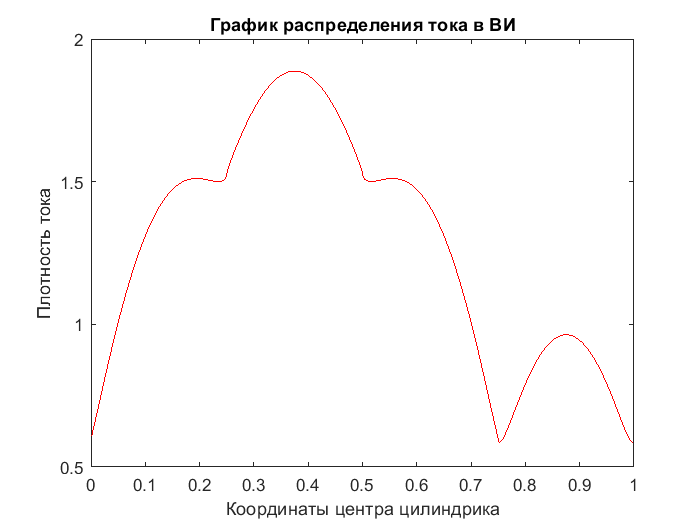

% построение графика респределения токов в ВИ

figure;
% plot(n_for_graf/(4*N), abs(Ic/max(Ic)), 'r');
plot((n_for_graf-0.5)/(4*N), abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');

Запись в файл

% for n=1:4*N
%     Inorm = abs(I);
%     fprintf(f01,' %10.5f %10.5f\n', (n_for_graf(n)-0.5)/(4*N), Inorm(n));
% end
% 
% fclose(f01);

Cтроили для ленты - проверка

% for m=1:N
%     cx = -1i*k*cosd(phi_grad);
%     cz = -1i*k*sind(phi_grad);
%     % участок номер 1
%     xm = S(1).x(m);
%     zm = S(1).z(m);
%     Eix1(m,1) = +4*1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле
% end
% 
% I = Es11\Eix1;        
% 
% % номера ВИ для графика 
% n_for_graf = zeros(1, N);
% for i = 1 : N
%      n_for_graf(i) = i;
% end
% 
% % построение графика респределения токов в ВИ
% figure;
% % plot(n_for_graf/(4*N), abs(Ic/max(Ic)), 'r');
% plot(n_for_graf, abs(I), 'r');
% title('График распределения тока в ВИ'); 
% xlabel('Координаты центра цилиндрика'); 
% ylabel('Плотность тока');


% r_x_plus = sqrt((xmn+delta)^2+zmn^2);
% r_x_minus = sqrt((xmn-delta)^2+zmn^2);
% 
% Ez = zmn/r_x_minus*besselh(1, 1, k*r_x_minus) - zmn/r_x_plus*besselh(k*r_x_plus);
% Ex = xmn-delta/r_x_minus*besselh(k*r_x_minus) - xmn+delta/r_x_plus*besselh(1, 1, k*r_x_plus) + Z; 

% dx = 1
% xm = 1
% xn = 0
% xmn = xn-xm;
% k_xm_plus = k*(abs(xmn)+delta);
% k_xm_minus = k*(abs(xmn)-delta);
% 
% D = kdx + (1i*2*k/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-dx );
%     
% D1 = kdx*(1+(1i/pi)*(3*log(3*gamma*kd4)-log(gamma*kd4)-2));
% 
% D == D1



Cравним ошибку вычисления интеграла 2мя способами

Находимся на 1м участке

#### Находимся на 1м участке. (m = 1, n = 1)

#### Нужно Ex от всех


for m = 1 : N
    xm = S(1).x(m);
    zm = S(1).z(m);
    
    for n = 1 : N
        xn = S(1).x(n);
        zn = S(1).z(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2+zmn^2);
        
        r_x_plus = sqrt((xmn+delta)^2+zmn^2);
        r_x_minus = sqrt((xmn-delta)^2+zmn^2);
        r_z_plus = sqrt(xmn^2+(zmn+delta)^2);
        r_z_minus = sqrt(xmn^2+(zmn-delta)^2);
        
        if r < 0.0001*dx
            Z_metod_1(m,n) = 1;
            Z_metod_2(m,n) = 1;
        else 
            k_xm_plus = k*(abs(xmn)+delta);
            k_xm_minus = k*(abs(xmn)-delta);
            k_zm_plus = k*(abs(zmn)+delta);
            k_zm_minus = k*(abs(zmn)-delta);
            
            Z_metod_2(m,n) = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
            
            f2 = besselh(0,1,k*r);
            Z_metod_1(m,n) = k*dx*f2;
        end   
    end
end

Z_Error_methods = Z_metod_1-Z_metod_1

Z_Error_methods =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 

## ЭПР


% tx = [1 0 -1 0];
% tz = [0 1 0 -1];
% 
% for p = 1 : 721
%     Sum_H = 0;
%     phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
%     phi_for_graf_DA(p) = (p-1)/2; % угол для графика
%     
%     cx = - 1i*k*cosd(phi);
%     cz = - 1i*k*sind(phi);
%     
%    
%     for number_line = 1 : 4
%         for n = 1 : N
%             txn = tx(number_line);
%             tzn = tz(number_line);
%             xn = S(number_line).x(n);
%             zn = S(number_line).z(n);
%             
%             Sum_H = Sum_H + 1/4*I(n + N*(number_line-1))*k*dx*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
%         end
%     end
%      
% RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));
% 
% end
% 
% % график поля в дальней зоне от угла налюденя (не нормированный)
% figure;
% plot(phi_for_graf_DA ,RCS,'r-');
% title('График распределения поля в дальней зоне'); 
% xlim([0 360])
% xlabel('Угол, град'); 
% ylabel('ЭПР');

tx = [1 0 -1 0];
tz = [0 1 0 -1];
X = [S(1).x S(2).x S(3).x S(4).x];
Z = [S(1).z S(2).z S(3).z S(4).z];

Tz = [repmat(tz(1),1,N) repmat(tz(2),1,N) repmat(tz(3),1,N) repmat(tz(4),1,N)];
Tx = [repmat(tx(1),1,N) repmat(tx(2),1,N) repmat(tx(3),1,N) repmat(tx(4),1,N)];

for p = 1 : 721
    Sum_H = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k*cosd(phi);
    cz = - 1i*k*sind(phi);
    

        for n = 1 : 4*N
            txn = Tx(n);
            tzn = Tz(n);
            xn = X(n);
            zn = Z(n);
            
            Sum_H = Sum_H + 1/4*I(n)*k*dx*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
        end
    
RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA ,RCS,'r-');

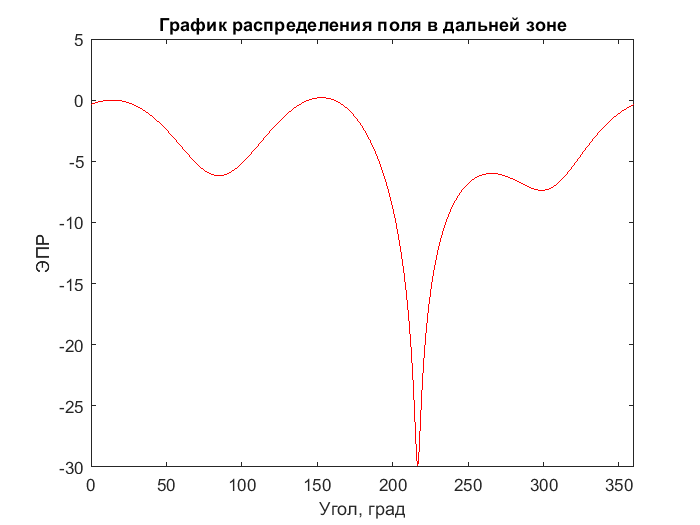

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Запись в файл

% for p = 1 : 721
%     fprintf(f02, ' %10.5f %10.5f\n', phi_for_graf_DA(p), RCS(p));
% end
% fclose(f02);